% Add path
addpath(genpath('.\Motion'));
addpath(genpath('.\Registration'));
addpath(genpath('.\SVD'));
addpath(genpath('.\KeyPoints'));

clear;
clc;

% Preview motion data to manually select indexes
% Oral Task: maximum open and close, choose by z-axis
% Oral Task: lateral left-right movement, choose by x-axis
% Oral Task: anterior-posterior movement, choose by y-axis

% Params
dataPath = 'C:\Users\Yaolab\Box\6monthVs.12month\Cases\CARSH_00177\11-24-2020\';
motionDataCSVFilePath   = [dataPath, 'Motion_csv\11.csv'];       % Motion data path
skullGeomagicMarkersPath = [dataPath, 'GeomagicFiles\Skull_Markers_Coordinates.csv'];
titleStr                = 'Maximum open and close';             % Name of oral task

% Read motion data from the CSV file
m_motionData = loadMotionCSVData(motionDataCSVFilePath);

Frame: missing 0 out of 3901 data.
TypeNameTimeSeconds: missing 0 out of 3901 data.
RigidBodyMandibleRotationX: missing 940 out of 3901 data.
RigidBodyMandibleRotationY: missing 940 out of 3901 data.
RigidBodyMandibleRotationZ: missing 940 out of 3901 data.
RigidBodyMandibleRotationW: missing 940 out of 3901 data.
RigidBodyMandiblePositionX: missing 940 out of 3901 data.
RigidBodyMandiblePositionY: missing 940 out of 3901 data.
RigidBodyMandiblePositionZ: missing 940 out of 3901 data.
RigidBodyMandibleMeanMarkerError: missing 940 out of 3901 data.
RigidBodyMarkerMandibleMarker1PositionX: missing 940 out of 3901 data.
RigidBodyMarkerMandibleMarker1PositionY: missing 940 out of 3901 data.
RigidBodyMarkerMandibleMarker1PositionZ: missing 940 out of 3901 data.
RigidBodyMarkerMandibleMarker1MarkerQuality: missing 940 out of 3901 data.
RigidBodyMarkerMandibleMarker2PositionX: missing 940 out of 3901 data.
RigidBodyMarkerMandibleMarker2PositionY: missing 940 out of 3901 data.
RigidBodyMarkerM


% Read skull markers position in CBCT 
m_skullGeomagicMarkers = loadSkullGeomagicPoints(skullGeomagicMarkersPath);

% Reorder skull markers order based on relative distance relationship of markers
m_motionData = reorderSkullMarkers(m_motionData, m_skullGeomagicMarkers);

% Get mandible markers position based on skull markers in CBCT, skull
% markers in motion, mandible markers in motion
m_mandibleGeomagicPoints = registerMandibleBySkull(m_motionData, m_skullGeomagicMarkers);

% Fix skull position based on skull markers in CBCT
m_motionData = fixSkullMarkers(m_motionData, m_skullGeomagicMarkers);

Frame 1, Alignment accuracy: 14.069809
Frame 2, Alignment accuracy: 14.069805
Frame 3, Alignment accuracy: 14.069805
Frame 4, Alignment accuracy: 14.069808
Frame 5, Alignment accuracy: 14.069800
Frame 6, Alignment accuracy: 14.069804
Frame 7, Alignment accuracy: 14.069807
Frame 8, Alignment accuracy: 14.069806
Frame 9, Alignment accuracy: 14.069808
Frame 10, Alignment accuracy: 14.069809
Frame 11, Alignment accuracy: 14.069808
Frame 12, Alignment accuracy: 14.069810
Frame 13, Alignment accuracy: 14.069812
Frame 14, Alignment accuracy: 14.069812
Frame 15, Alignment accuracy: 14.069809
Frame 16, Alignment accuracy: 14.069800
Frame 17, Alignment accuracy: 14.069803
Frame 18, Alignment accuracy: 14.069804
Frame 19, Alignment accuracy: 14.069806
Frame 20, Alignment accuracy: 14.069806
Frame 21, Alignment accuracy: 14.069815
Frame 22, Alignment accuracy: 14.069818
Frame 23, Alignment accuracy: 14.069807
Frame 24, Alignment accuracy: 14.069801
Frame 25, Alignment accuracy: 14.069796
Frame 26,

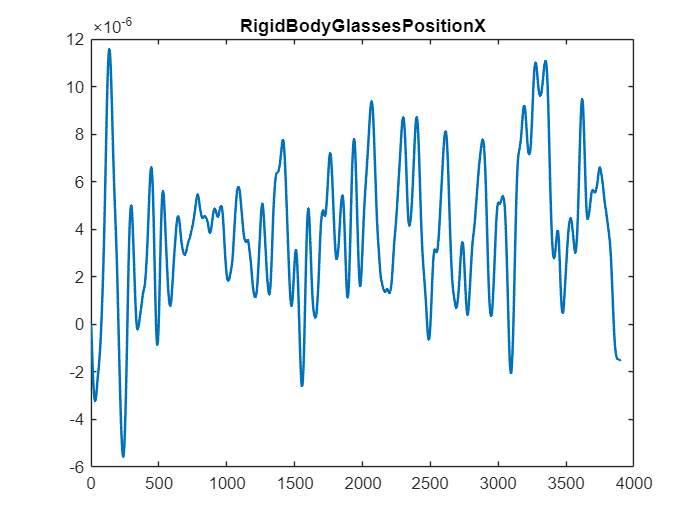

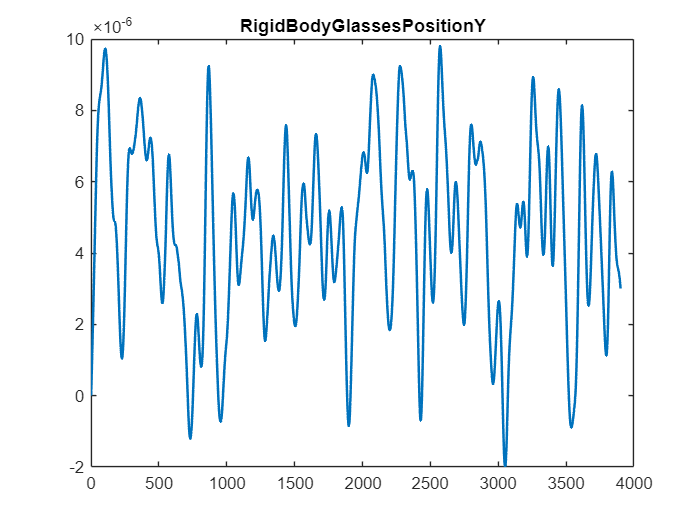

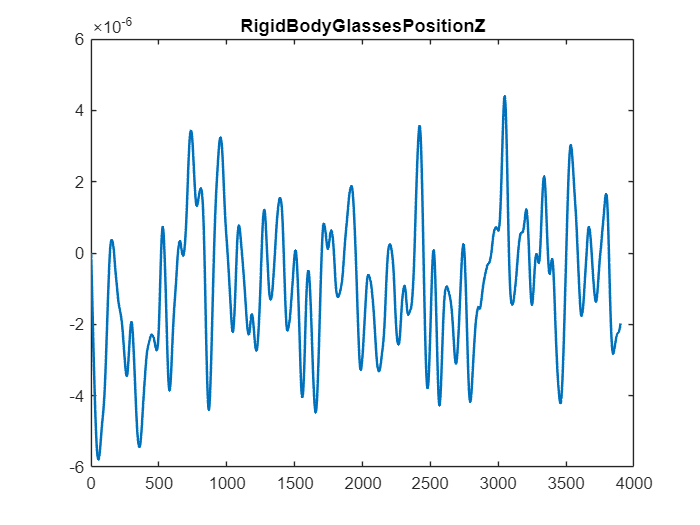

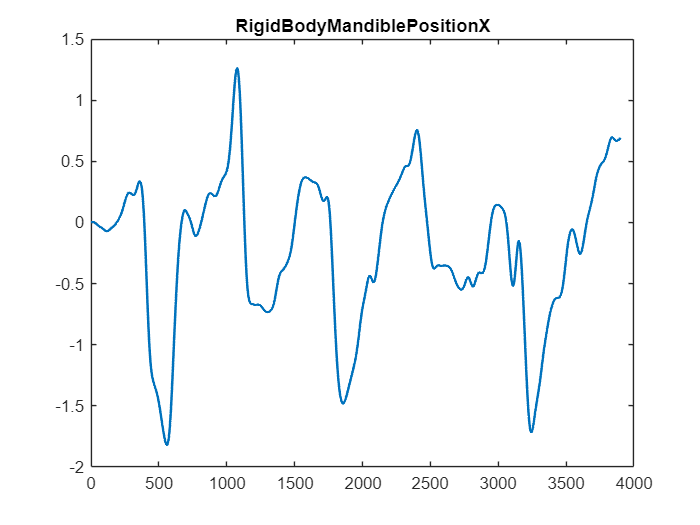

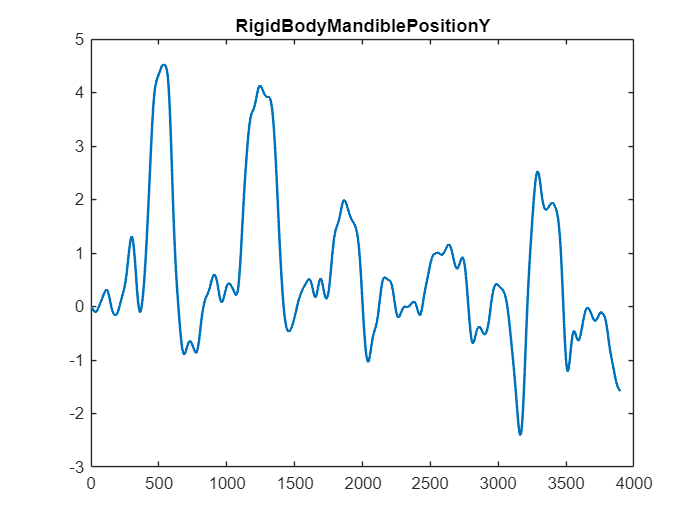

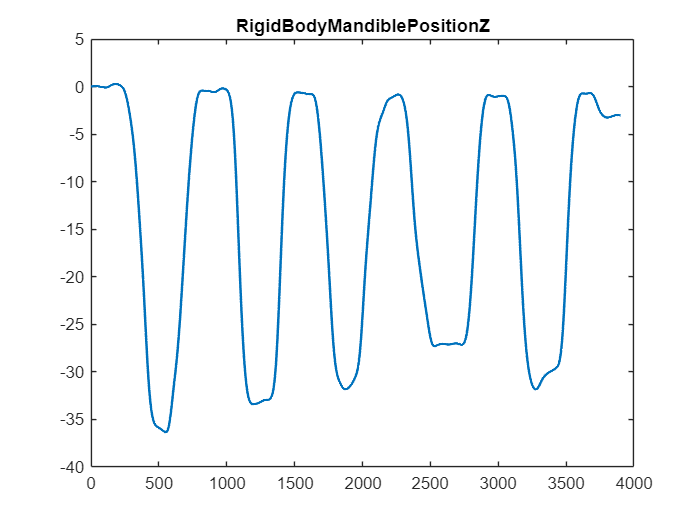

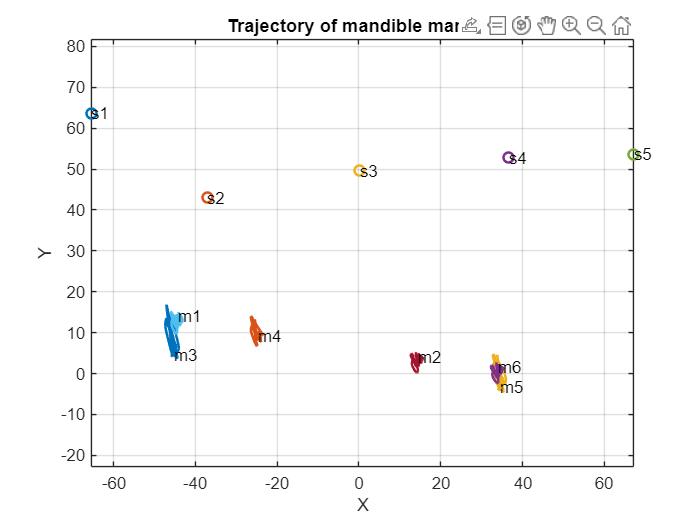


% Filter motion data
m_motionData = filterMotionData(m_motionData);

% Smooth motion data
m_motionData = smoothMotionData(m_motionData);

% View motion data
viewMotionData(m_motionData)

% Remove path
rmpath(genpath('.\Motion'));
rmpath(genpath('.\Registration'));
rmpath(genpath('.\SVD'));
rmpath(genpath('.\KeyPoints'));